## Cinematica

clear
close all
omega=20.53

omega = 20.5300

VelRPM=omega*30/pi

VelRPM = 196.0471

## Cinética

Torque=8.4

Torque = 8.4000

### Disco

D_disco=0.08;
R_disco=0.5*D_disco;
F_torque=Torque/R_disco*0.2248089431

F_torque = 47.2099

CoefFriccion=1.35 %AL-AL

CoefFriccion = 1.3500

F_axial=F_torque/CoefFriccion

F_axial = 34.9703

### Polea

alpha=68.9

alpha = 68.9000

D=0.45

D = 0.4500

R=D/2

R = 0.2250

F_torque=Torque/(R*cosd(alpha))*0.2248089431

F_torque = 23.3137

n=1000;
v=D*n/19.1

v = 23.5602

Pd=0.238;
C3=0.83;
M=0,074;

M = 0

N=1;
T_used=510*(2.2-C3)*Pd/(C3*N*v)+M*v^2/1.11%*0.2248089431;

T_used = 8.5037

T_new=1.5*T_used*0.2248089431

T_new = 2.8676

T1=T_new

T1 = 2.8676

T2=T_new+F_torque

T2 = 26.1813

Torque=(T2-T1)*cosd(alpha)*R

Torque = 1.8884

theta1=32

theta1 = 32

theta2=74.2

theta2 = 74.2000

Fx=T2*cosd(32)+T1*cosd(74.2)

Fx = 22.9838

Fy=-(T2*sind(32)+T1*sind(74.2))

Fy = -16.6332

## Fatiga

D_1=3/4 %polea

D_1 = 0.7500

D_2=1 %"apoyo"

D_2 = 1

D_3=1+1/4 %"Tornillo"

D_3 = 1.2500

D_4=3.14 %"Tornillo"

D_4 = 3.1400

D_5=1 %Apoyo 2

D_5 = 1


M_1=4.05*8.850

M_1 = 35.8425

M_2=5.76*8.850

M_2 = 50.9760

M_3=0.57*8.850

M_3 = 5.0445


Torque=8.4*8.850

Torque = 74.3400

Número de ciclos

An=10;
Tasa=2;
Arepas=20;
Semanas=52;
N_ciclos=An*Arepas/Tasa*VelRPM*Semanas

N_ciclos = 1.0194e+06

Material: Aluminio 2017

S_ut=26000

S_ut = 26000

S_y=10000

S_y = 10000

### Sección 1 hombro

rHombro=2/25.4;
A_t=0.25*pi*(D_1)^2;
neuberF=cN(S_ut/1000)

neuberF = 0.1755

neuberT=cN(S_ut/1000+20)

neuberT = 0.1335

ktH=ktBending(D_1,D_2,rHombro)

ktH = 1.6830

ktsH=ktsTorsion(D_1,D_2,rHombro)

ktsH = 1.3759

ktaH=1.76

ktaH = 1.7600

qFlexion=1/(1+neuberF/sqrt(rHombro))

qFlexion = 0.6152

qTorsion=1/(1+neuberT/sqrt(rHombro))

qTorsion = 0.6776

Kf=1+qFlexion*(ktH-1)

Kf = 1.4202

Kfs=1+qTorsion*(ktsH-1)

Kfs = 1.2547

kfaH=1+qFlexion*(ktaH-1)

kfaH = 1.4676

Ma=M_1;
Ta=0;
Tm=Torque;
sigma1=ktH*32*Ma/(pi*D_1^3)+ktaH*F_axial/A_t

sigma1 = 1.5958e+03

tau1=ktsH*16*Tm/(pi*D_1^3)

tau1 = 1.2348e+03

SigmaVM=sqrt(3*tau1^2+sigma1^2)

SigmaVM = 2.6684e+03

FsEst=S_y/SigmaVM

FsEst = 3.7475

kilo=1000;
Se1=S_ut*0.5;
Ccar=0.7;

D_eq para un eje cilindrico es igual a su diámetro:

Ctam=CoefTamano(D_1)

Ctam = 0.8936

Eje maquinado:

Csup=2.7*(S_ut/1000)^(-0.265)

Csup = 1.1387

Csup=1

Csup = 1

Temperatura menor a 450°:

Ctem=1

Ctem = 1

Confiabilidad del 99.9%:

Ccon=0.753;
Se=Ccar*Ctam*Csup*Ctem*Ccon*Se1

Se = 6.1232e+03

sigmaA=Kf*32*Ma/(pi*D_1^3)

sigmaA = 1.2290e+03

tauM=Kfs*16*Tm/(pi*D_1^3)

tauM = 1.1260e+03

sigmaAxial=kfaH*F_axial/A_t

sigmaAxial = 116.1674

sigmaM=sqrt(3*tauM^2+sigmaAxial^2)

sigmaM = 1.9538e+03

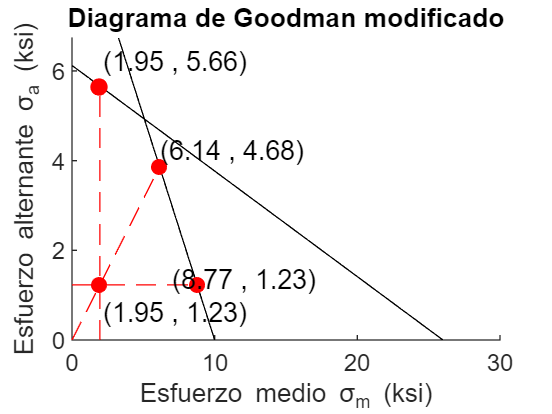

FS1 = 4.6077

FS2 = 3.3435

FS3 = 4.4893

FS = 3.3435

FS=diagramaGoodman(sigmaA/kilo,sigmaM/kilo,S_ut/kilo,S_y/kilo,Se/kilo,1)

### Sección 1 cuñero

rCuna=2/32;
rd=rCuna/D_1;
ktC=ktCuna(D_1,rd)

ktC = 1.6204

ktsC=ktsCuna(D_1,rd)

ktsC = 2.1221

qFlexion=1/(1+neuberF/sqrt(rCuna));
qTorsion=1/(1+neuberT/sqrt(rCuna));
Kf=1+qFlexion*(ktC-1)

Kf = 1.3645

Kfs=1+qTorsion*(ktsC-1)

Kfs = 1.7314

Ma=M_1;
Tm=Torque;
kilo=1000;
sigma1=ktC*32*Ma/(pi*D_1^3)+F_axial/A_t

sigma1 = 1.4815e+03

tau1=ktsC*16*Tm/(pi*D_1^3)

tau1 = 1.9044e+03

SigmaVM=sqrt(3*tau1^2+sigma1^2)

SigmaVM = 3.6160e+03

FsEst=S_y/SigmaVM

FsEst = 2.7655

Ctam=CoefTamano(D_1)

Ctam = 0.8936

Se=Ccar*Ctam*Csup*Ctem*Ccon*Se1

Se = 6.1232e+03

sigmaA=Kf*32*Ma/(pi*D_1^3)

sigmaA = 1.1809e+03

tauM=Kfs*16*Tm/(pi*D_1^3)

tauM = 1.5538e+03

sigmaAxial=F_axial/A_t

sigmaAxial = 79.1565

sigmaM=sqrt(3*tauM^2+sigmaAxial^2)

sigmaM = 2.6925e+03

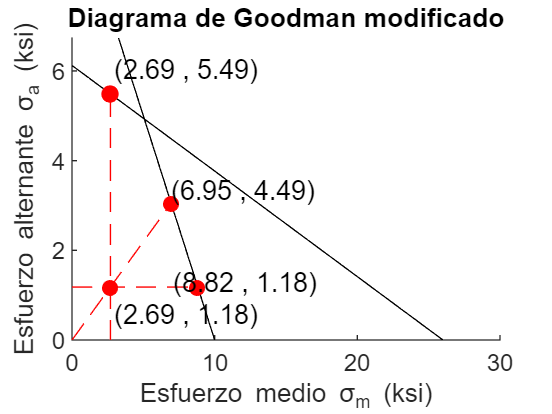

FS1 = 4.6484

FS2 = 2.8140

FS3 = 3.2755

FS = 2.8140

FS=diagramaGoodman(sigmaA/kilo,sigmaM/kilo,S_ut/kilo,S_y/kilo,Se/kilo,1)

### Seccion 2 momento máx

A_t=0.25*pi*(D_2)^2;
Ctam=CoefTamano(D_2)

Ctam = 0.8690

Se=Ccar*Ctam*Csup*Ctem*Ccon*Se1

Se = 5.9546e+03

Ma=M_2;
Tm=Torque;
sigma1=32*Ma/(pi*D_2^3)+F_axial/A_t

sigma1 = 563.7628

tau1=16*Tm/(pi*D_2^3)

tau1 = 378.6105

SigmaVM=sqrt(3*tau1^2+sigma1^2)

SigmaVM = 864.7926

FsEst=S_y/SigmaVM

FsEst = 11.5635

sigmaA=32*Ma/(pi*D_2^3)

sigmaA = 519.2373

tauM=16*Tm/(pi*D_2^3);
sigmaAxial=F_axial/A_t;
sigmaM=sqrt(3*tauM^2+sigmaAxial^2)

sigmaM = 657.2825

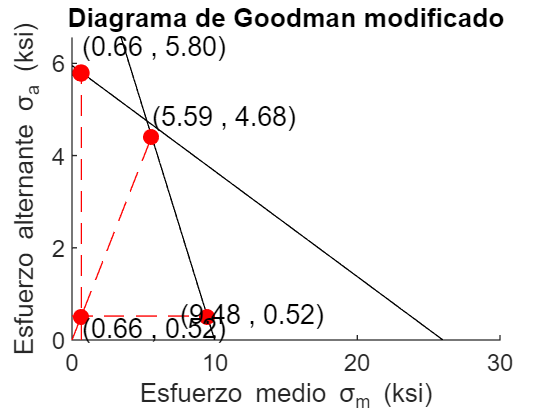

FS1 = 11.1782

FS2 = 8.6969

FS3 = 14.4242

FS = 8.6969

FS=diagramaGoodman(sigmaA/kilo,sigmaM/kilo,S_ut/kilo,S_y/kilo,Se/kilo,1)

### Seccion 2 hombro 

rHombro=2/25.4;
A_t=0.25*pi*(D_2)^2;
ktH=ktBending(D_2,D_3,rHombro)

ktH = 1.7790

ktsH=ktsTorsion(D_2,D_3,rHombro)

ktsH = 1.4385

ktaH=1.84

ktaH = 1.8400

sigma1=ktH*32*Ma/(pi*D_2^3)+ktaH*F_axial/A_t

sigma1 = 1.0056e+03

tau1=ktsH*16*Tm/(pi*D_2^3)

tau1 = 544.6213

SigmaVM=sqrt(3*tau1^2+sigma1^2)

SigmaVM = 1.3788e+03

FsEst=S_y/SigmaVM

FsEst = 7.2526

qFlexion=1/(1+neuberF/sqrt(rHombro));
qTorsion=1/(1+neuberT/sqrt(rHombro));
Kf=1+qFlexion*(ktH-1)

Kf = 1.4792

Kfs=1+qTorsion*(ktsH-1)

Kfs = 1.2971

kfaH=1+qFlexion*(ktaH-1)

kfaH = 1.5168

Ctam=CoefTamano(D_2);
Se=Ccar*Ctam*Csup*Ctem*Ccon*Se1;
Ma=M_3;
Ta=0;
Tm=Torque;
sigmaA=Kf*32*Ma/(pi*D_2^3)

sigmaA = 76.0076

tauM=Kfs*16*Tm/(pi*D_2^3);
sigmaAxial=kfaH*F_axial/A_t;
sigmaM=sqrt(3*tauM^2+sigmaAxial^2)

sigmaM = 853.2728

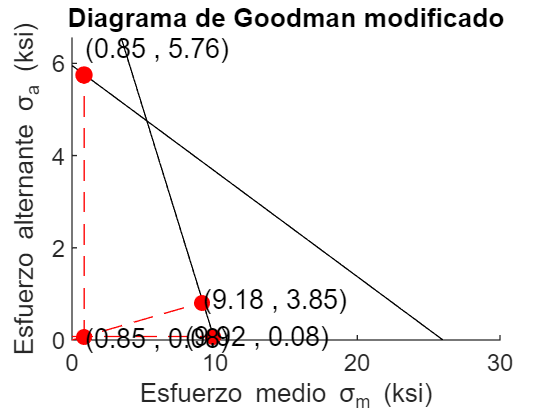

FS1 = 75.7717

FS2 = 11.6234

FS3 = 11.6305

FS = 11.6234

FS=diagramaGoodman(sigmaA/kilo,sigmaM/kilo,S_ut/kilo,S_y/kilo,Se/kilo,1)

## Cuñas

Para las cuñas asociadas a los cuñeros de las dos poleas se van a utilizar cuñas rectangulares de aluminio 2017, el mismo que el eje, pero para cumplir un FS=1.5

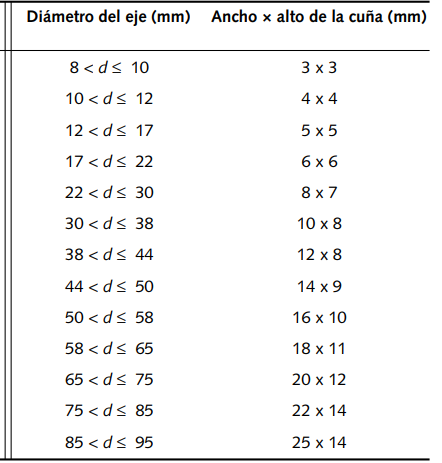

FSC=2;
D_1*25.4

ans = 19.0500

W2=6/25.4;
H2=6/25.4;
FC=M_1/(0.5*D_1);
LCc=sqrt(3)*FC*FSC/(W2*S_y)

L2C = 0.1402

LCa=2*FC*FSC/(H2*S_y)

L2A = 0.1618

Lcuna_D3=max([LCc LCa])

Lcuna_D3 = 0.1618

## Velocidad crítica

densidad=0.102; %lb/in3
g=386.1;
L_1=1.77

L_1 = 1.7700

L_2=2.36

L_2 = 2.3600

L_3=4.73

L_3 = 4.7300

L_4=0.39

L_4 = 0.3900

L_5=0.79

L_5 = 0.7900

D_1 = 0.7500

D_2 = 1

D_3 = 1.2500

D_4 = 3.1400

D_5 = 1

Vl=[L_1 L_2 L_3 L_4 L_5];
Vd=[D_1 D_2 D_3 D_4 D_5];
Vx=[L_1/2, L_1+0.5*L_2,L_1+L_2+L_3*0.5,L_1+L_2+L_3+L_4*0.5, L_1+L_2+L_3+L_4+0.5*L_5]*25.4

Vx =    22.4790   74.9300  164.9730  229.9970  244.9830


Vw=0.25*pi.*Vd.*Vl.*densidad

Vw =     0.1063    0.1891    0.4737    0.0981    0.0633


Vy=[9.22 2.97 4.18 0.9 0]*10^-3/25.4

Vy = 	1.0e+-3 *

    0.3630    0.1169    0.1646    0.0354         0


Wc=7.2*9.81;
Xc=9.22*10^-3/25.4;
Vw=[Vw Wc];
Vy=[Vy Xc];
w_1=sqrt(g*sum(Vw.*Vy)/sum(Vw.*Vy.^2))*30/pi

w_1 = 9.8602e+03

Nvc=w_1/VelRPM

Nvc = 50.2950

function kt=ktBending(d,D,r)
h=0.5*(D-d);
x=h/r;
if(x<2)
    C1=0.947+1.206*sqrt(x)-0.131*x;
    C2=0.022-3.405*sqrt(x)+0.915*x;
    C3=0.869+1.777*sqrt(x)-0.555*x;
    C4=-0.81+0.422*sqrt(x)-0.260*x;
else
    C1=1.232+0.832*sqrt(x)-0.008*x;
    C2=-3.813+0.968*sqrt(x)-0.26*x;
    C3=7.423-4.868*sqrt(x)+0.869*x;
    C4=-3.839+3.070*sqrt(x)-0.6*x;
end
kt=C1+C2*(2*h/D)+C3*(2*h/D)^2+C4*(2*h/D)^3;
end


function kts =ktsTorsion(d,D,r)
h=0.5*(D-d);
x=h/r;
C1=0.905+0.783*sqrt(x)-0.075*x;
C2=-0.437-1.969*sqrt(x)+0.553*x;
C3=1.557+1.073*sqrt(x)-0.578*x;
C4=-1.061+0.171*sqrt(x)+0.086*x;
kts=C1+C2*(2*h/D)+C3*(2*h/D)^2+C4*(2*h/D)^3;
end

function kt = ktCuna(d,c)
r=c*d;
x=r/d;
kt=1.426+0.1643*(0.1/x)-0.0019*(0.1/x)^2;
end

function kts = ktsCuna(d,c)
r=c*d;
x=r/d;
kts=1.953+0.1434*(0.1/x)-0.0021*(0.1/x)^2;
end


function Ctam=CoefTamano(D)
deq=D;
if(deq<0.3)
    Ctam=1;
elseif(deq<10)
    Ctam=0.869*(deq)^-0.097;
else
    Ctam=0.6;
end
end

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5 x6
if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;
Fr2=sigmaA.*x6/sigmaM==Sy-x6;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));
FSm2=double(solve(Fr2,x6));
if(FSy2<FSy)
    FSy=FSy2;
end

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")

if(goodManM(sigmaM)<lineaF(sigmaM))
stem(sigmaM,goodManM(sigmaM),"r--","filled")
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
else
stem(sigmaM,lineaF(sigmaM),"r--","filled")
text(1.1*sigmaM,1.1*lineaF(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,lineaF(sigmaM)))
end


if(FSm2<FSm)
    FSm=FSm2;
    scatter(FSm,lineaF(FSm),"r","filled")
    text(FSm,1.1*lineaF(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
else
scatter(FSm,goodManM(FSm),"r","filled")
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
end
fplot(lineaC,[0 FSm],"r--")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (ksi)")
ylabel("Esfuerzo alternante \sigma_a (ksi)")
title("Diagrama de Goodman modificado")


if(goodManM(sigmaM)<lineaF(sigmaM))
FS1=goodManM(sigmaM)/sigmaA
else
FS1=lineaF(sigmaM)/sigmaA
end

FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(8*sigmaM,2*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(8*sigmaM,1.1*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.1*FSm,1.1*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,2*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (ksi)")
ylabel("Esfuerzo alternante \sigma_a (ksi)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end


function cn = cN(Sut)
    cn = 0.245799 - ((0.307794e-2)*Sut) + ((0.150874e-4)*(Sut^2)) - ((0.266978e-7)*(Sut^3));
end